#  Chapter 6 - State Space Design of Control Systems 

##  Section 6 - Minimum Order Observers

clear all; clc

**Notes: **

Minimum Order Observer: In practice, some state variables can be measured accurately and therefore do not need an estimate. If you have a state vector, x, with n length and an output vector, y, with m length...you only need to estimate (n - m) state variables. The reduced/minimum-order observer becomes an (n - m)th order observer, as shown in the figure below. 

Note: If the measurement output variables involve significant noise/ is relatively inaccurate, then the use of a full order observer may result in better system performance. 

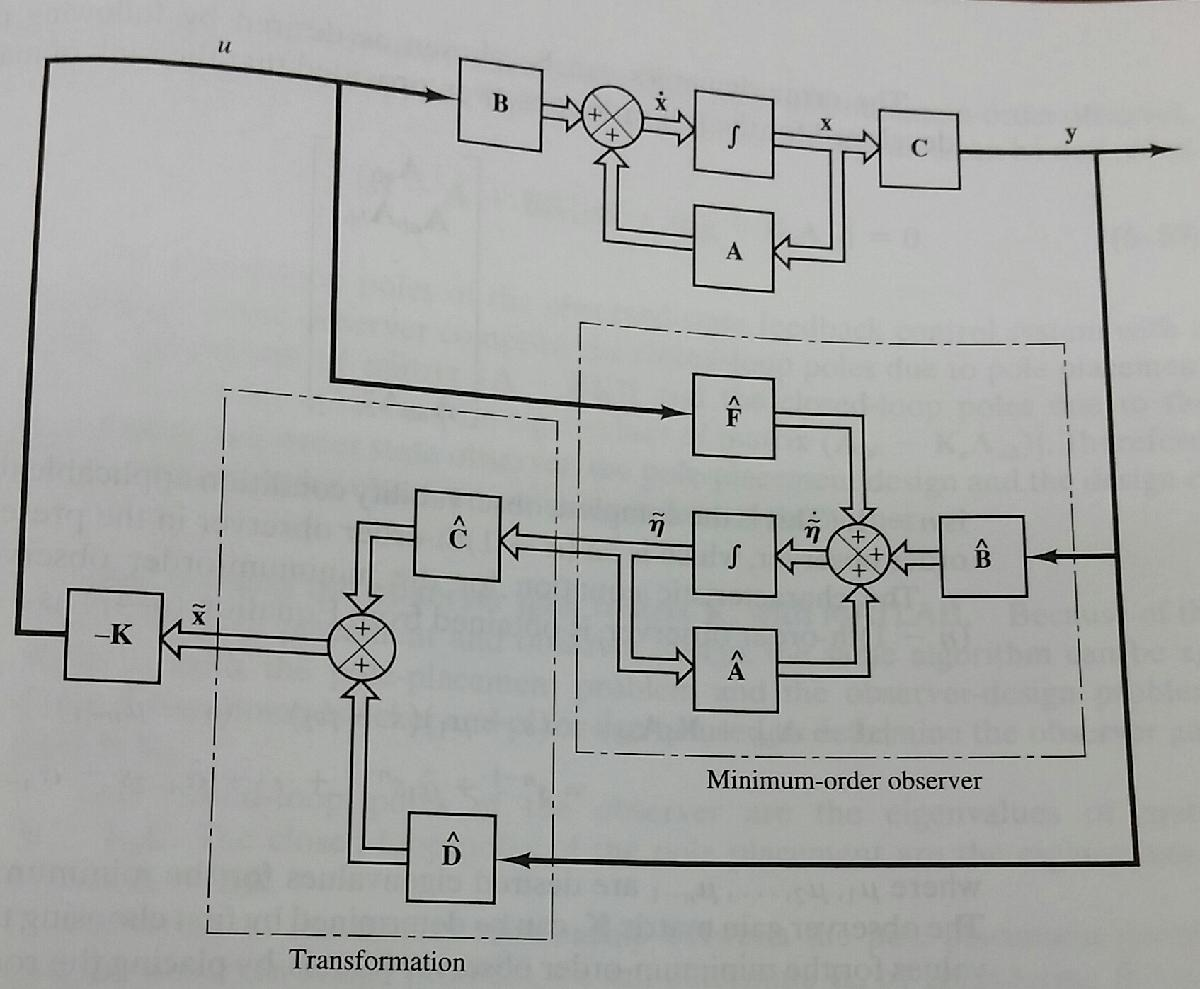

You will take the input matrix and divide it into the measurable and unmeasureable states. This will determine the order/states to use in the observer. See pages 335-340 for mathematical derivation. 

Observed-State Feedback controly system w minimum order observer :  Similar to the full-order state observer, the closed-loop poles of the observed-state feedback control consist of the poles due to the pole-placement design alone, plus the poles due to the observer design alone. 

Deterimining the observer gain matrix, K_e, with MATLAB: Same as before...the same algorithm can be applied to both the pole-placement problem and the observer-design problem. (Use both 'acker' and 'place' matlab functions)

## 6-8 Determine the minimum-order observer gain, Ke

% System dynamics
A = [ 0 1 0; 0 0 1; -6 -11 -6 ];
B = [0; 0; 1];
C = [ 1 0 0];
D = [0];

% Define closed-loop poles 
J = [-2+j*2*sqrt(3) -2-j*2*sqrt(3) -6];

% Solve for necessary state-feedback gain matrix, K
K = acker(A, B, J)

K =    90.0000   29.0000    4.0000


Assume output, y, is measured accurately, so the state variable x1 (which is equal to y) does not need to be estimated. Next, use the characteristic equation for the minimum-order observer and Ackermann's formula to determine K_e. See page 343 for derivation. 

% From characteristic equation for minimum-order observer (know x1...so basically remove)
Abb = [0 1; -11 -6];
Aab = [1 0];

% Choose desired observer poles
L = [-10 -10];

% Solve for K_e
Ke = acker(Abb', Aab', L)

Ke =     14     5


## 6-9 Using the mechanical system, design a regulator system that will maintain the zero position in the presence of a disturbance. 

Use the pole-placement-with-observer approach. Use the specified desired closed-loop poles for the pole placement part. Design the regulator system that will maintain the zero position of (y1 = 0, and y2 = 0). The desired poles for the state-feedback and min-order observer and the initial conditions of the system are given. 

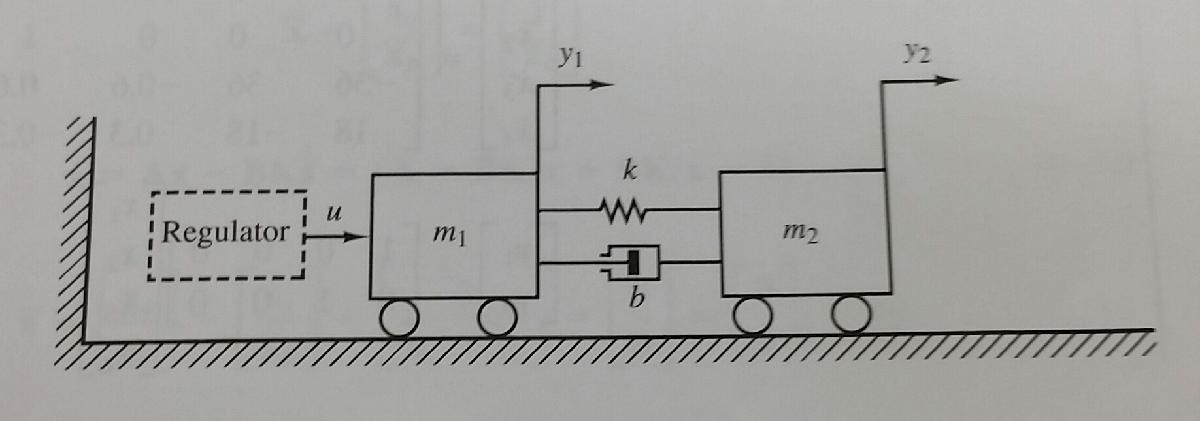

Step 1 : EOM 

Step 2: Substitute and determine state-space equations for state variables : y1, y2, y1_dot,     y2_dot.

A = [0 0 1 0; 0 0 0 1; -36 36 -0.6 0.6; 18 -18 0.3 -0.3];
B = [0; 0; 1; 0];
C = [1 0 0 0; 0 1 0 0];

Step 3: Define minimum-order observer conditions (remove the y1 and y2 terms...only keep y1_dot and y2_dot) 

Abb = [-0.6 0.6; 0.3 -0.3];
Aab = [1 0; 0 1];

Step 4: Determine the state feedback gain matrix (K) and observer gain matrix (Ke) from given pole-placements. 

% Desired closed-loop poles
J = [-2 + j*2*sqrt(3) -2 - j*2*sqrt(3) -10 -10];
% Desired minimum order observer poles
L = [-15 -16];

% Solve for K and Ke
K = acker(A, B, J)

K =   130.4444  -41.5556   23.1000   15.4185


Ke = place(Abb', Aab', L')

Ke =    14.4000    0.3000
    0.6000   15.7000


Step 5: Use gain matrices to determine the response to initial conditions. (see pg 348)

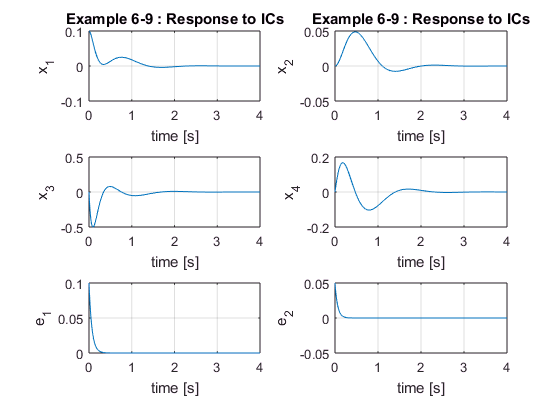

% define F matrix for observer
F = [0 0; 0 0; 1 0; 0 1];

% define system 
AA = [(A - B*K) (B*K*F); (zeros(2,4)) (Abb - Ke*Aab)];    %6x6 matrix\
sys = ss(AA, eye(6), eye(6), eye(6));

% response to initial conditions
t = 0:0.01:4; 
y = initial(sys, [0.1; 0; 0; 0; 0.1; 0.05], t);
out = eye(6)*y';

% plot
subplot(321); plot(t, out(1,:)),grid
title('Example 6-9 : Response to ICs'), xlabel('time [s]'), ylabel('x_1')
subplot(322); plot(t, out(2,:)),grid
title('Example 6-9 : Response to ICs'), xlabel('time [s]'), ylabel('x_2')
subplot(323); plot(t, out(3,:)),grid
xlabel('time [s]'), ylabel('x_3')
subplot(324); plot(t, out(4,:)),grid
xlabel('time [s]'), ylabel('x_4')
subplot(325); plot(t, out(5,:)),grid
xlabel('time [s]'), ylabel('e_1')
subplot(326); plot(t, out(6,:)),grid
xlabel('time [s]'), ylabel('e_2')

As you can see, the error for both masses approaches zero and the regulator system is valid. 